clear;

% % %GaussianBeam

r0 = 2;%光束半径
f = r0/13*sqrt(15^2-13^2);%透镜等效焦距
x0=-r0:0.2:r0;
y0=-r0:0.2:r0;%输入光点
i0 = length(x0);
j0 = length(y0);
phi = zeros(i0,j0);%单位面积的光功率
I0 = 0;
for i = 1:i0
    for j = 1:j0
        rho2 = (x0(i))^2 + (y0(j))^2;
        if(rho2 <= r0^2)
            phi(i,j) = exp(-2 * rho2 / r0^2);
            I0 = I0 + phi(i,j);
        end
    end
end
phi = phi./I0;


% % % 循环模块


tic

% % % OPT
% % %原点是F
% % %单位mm

r=0.08;%球半径
n1=1.33;%环境的n
n2=1.5;%球的n
r1 = 1;%计算范围


NL=20;
% fp=zeros(NL,NL);
% fs=zeros(NL,NL);
% fg=zeros(NL,NL);
fp=zeros(1,NL);
fs=zeros(1,NL);
fg=zeros(1,NL);

% for k=1:1:NL
   for l = 1:1:NL
        s=0;%球心的y坐标
    %     d=2/NL*k-1;%球心的z坐标
    %     s = 2/NL*k - 1;
        d = 2*r1/NL*l - r1;
        F=double(zeros(1,3));%力矢量
        Fs=double(zeros(1,3));%散射力矢量
        Fg=double(zeros(1,3));%梯度力矢量
    
% 以上要手動賦值


% % % % 单点计算
% 
% 
% tic
% 
% % % % OPT
% % % %原点是F
% % % %单位mm
%     
% f=1;%透镜焦距
% r=0.1*sqrt(2);%球半径
% n1=1.33;%环境的n
% n2=1.5;%球的n
% c=1;%光速
% 
% s=0.2;%球心的y坐标
% d=0;%球心的z坐标
% 
% x0=-1:0.1:1;
% y0=-1:0.1:1;%输入光点的屏坐标
% %     phi=ones(21);%单位面积的光功率
% F=double(zeros(1,3));%力矢量
% % Fs=double(zeros(1,3));%散射力矢量
% % Fg=double(zeros(1,3));%梯度力矢量
%     
% % 以上要手動賦值


    for i=1:i0
        for j=1:j0
            syms z;
            z=solve((z*x0(i)/f)^2+(-z*y0(j)/f-s)^2+(z-d)^2==r^2,z);
            if isreal(z(1))
                z=double((z(1))); % 取較小值
            else
                continue
            end
            x=double (-z*x0(i)/f);
            y=double (-z*y0(j)/f);
            
            % Vx表示向量x
            Vn=[x,y-s,z-d];
            Vn=Vn/norm(Vn);%单位法向量
            Vl=[x0(i),y0(j),-f];%射入径向量（的负数）
            Vl=Vl/norm(Vl);
            theta=double (acos(dot(Vn,Vl)));
            gamma=double (asin(n1/n2*sin(theta)));
            R=double ((((n2*cos(theta)-n1*cos(gamma))/(n2*cos(gamma)+n1*cos(theta)))^2+((n1*cos(theta)-n2*cos(gamma))/(n1*cos(gamma)+n2*cos(theta)))^2)/1);
            T=1-R;

            dFz=double(n1*phi(i,j)*(1+R*cos(2*theta)-T^2*(cos(2*theta-2*gamma)+R*cos(2*theta))/(1+R^2+2*R*cos(2*gamma))));
            dFy=double(n1*phi(i,j)*(-R*sin(2*theta)+T^2*(sin(2*theta-2*gamma)+R*sin(2*theta))/(1+R^2+2*R*cos(2*gamma))));
            Vk=Vn-dot(Vn,Vl).*Vl;
            if norm(Vk)
                F=F-dFz.*(Vl)+dFy.*Vk/norm(Vk);
                Fs=Fs-dFz.*(Vl);
                Fg=Fg+dFy.*Vk/norm(Vk);
            else
                F=F-dFz.*(Vl);
                Fs=Fs-dFz.*(Vl);
            end
           
        end
    end


% % % 循环输出

%     fp(k,l)=F(3);
%     fs(k,l)=Fs(3);
%     fg(k,l)=Fg(3);
    fp(1,l) = F(3);
    fs(1,l) = Fs(3);
    fg(1,l) = Fg(3);
    fp(1,l)

ans = 2.7997e-04

ans = 2.7997e-04

ans = 2.7997e-04

ans = 2.7997e-04

ans = 2.7997e-04

ans = 0.0064

ans = 0.0114

ans = 0.0308

ans = 0.2355

ans = 0.0282 + 0.0000i

ans = -0.0668

ans = 0.0022

ans = 0.0031

ans = 0.0024

ans = 2.7997e-04

ans = 2.7997e-04

ans = 2.7997e-04

ans = 2.7997e-04

ans = 2.7997e-04

ans = 2.7997e-04

    fs(1,l)

ans = 2.7997e-04

ans = 2.7997e-04

ans = 2.7997e-04

ans = 2.7997e-04

ans = 2.7997e-04

ans = 0.0044

ans = 0.0073

ans = 0.0165

ans = 0.0843

ans = 0.0282

ans = 0.0843

ans = 0.0165

ans = 0.0073

ans = 0.0044

ans = 2.7997e-04

ans = 2.7997e-04

ans = 2.7997e-04

ans = 2.7997e-04

ans = 2.7997e-04

ans = 2.7997e-04

    fg(1,l)

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0.0020

ans = 0.0042

ans = 0.0143

ans = 0.1511

ans = -5.5055e-10 + 4.3004e-10i

ans = -0.1511

ans = -0.0143

ans = -0.0042

ans = -0.0020

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

    l

l = 1

l = 2

l = 3

l = 4

l = 5

l = 6

l = 7

l = 8

l = 9

l = 10

l = 11

l = 12

l = 13

l = 14

l = 15

l = 16

l = 17

l = 18

l = 19

l = 20

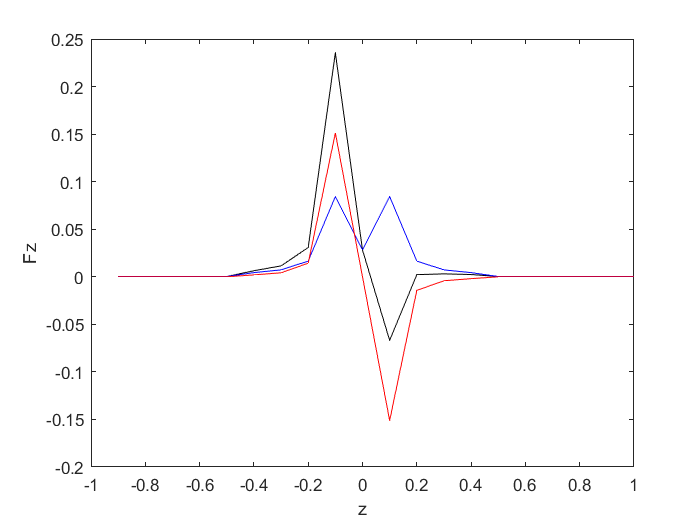

    end
% k
% end
% k1=1:NL;
% k2=2/NL*k1-1;
l1 = 1:NL;
l2 = 2/NL*l1 - 1;
plot(l2,fp,'k')
hold on
plot(l2,fs,'b')
plot(l2,fg,'r')
hold off
xlabel("z");
ylabel("Fz");
% mesh(k2,l2,fp)

% % % % 单点输出
% 
% F
% Fs
% Fg

toc

历时 545.509662 秒。
